# Design Task1

clc
clear

## Task1 a

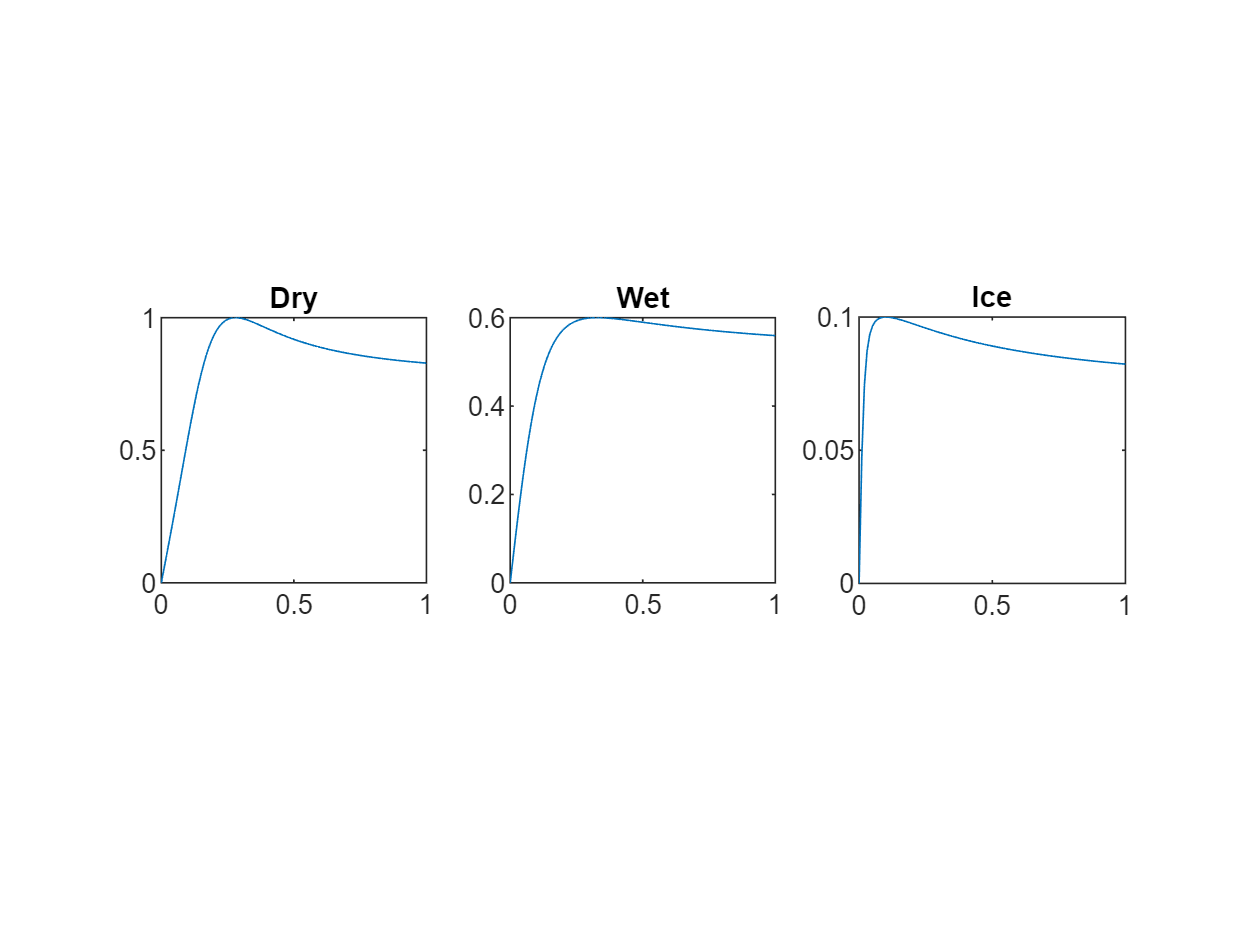

s_x = 0:0.01:1;
[mu_1, surface_type_1] = Sub_magic_tireformula(s_x,1);
[mu_2, surface_type_2] = Sub_magic_tireformula(s_x,2);
[mu_3, surface_type_3] = Sub_magic_tireformula(s_x,3);

figure
subplot(1,3,1)
plot(s_x, mu_1)
title(surface_type_1)
axis square

subplot(1,3,2)
plot(s_x, mu_2)
title(surface_type_2)
axis square
subplot(1,3,3)
plot(s_x, mu_3)
title(surface_type_3)
axis square

## Task1 b

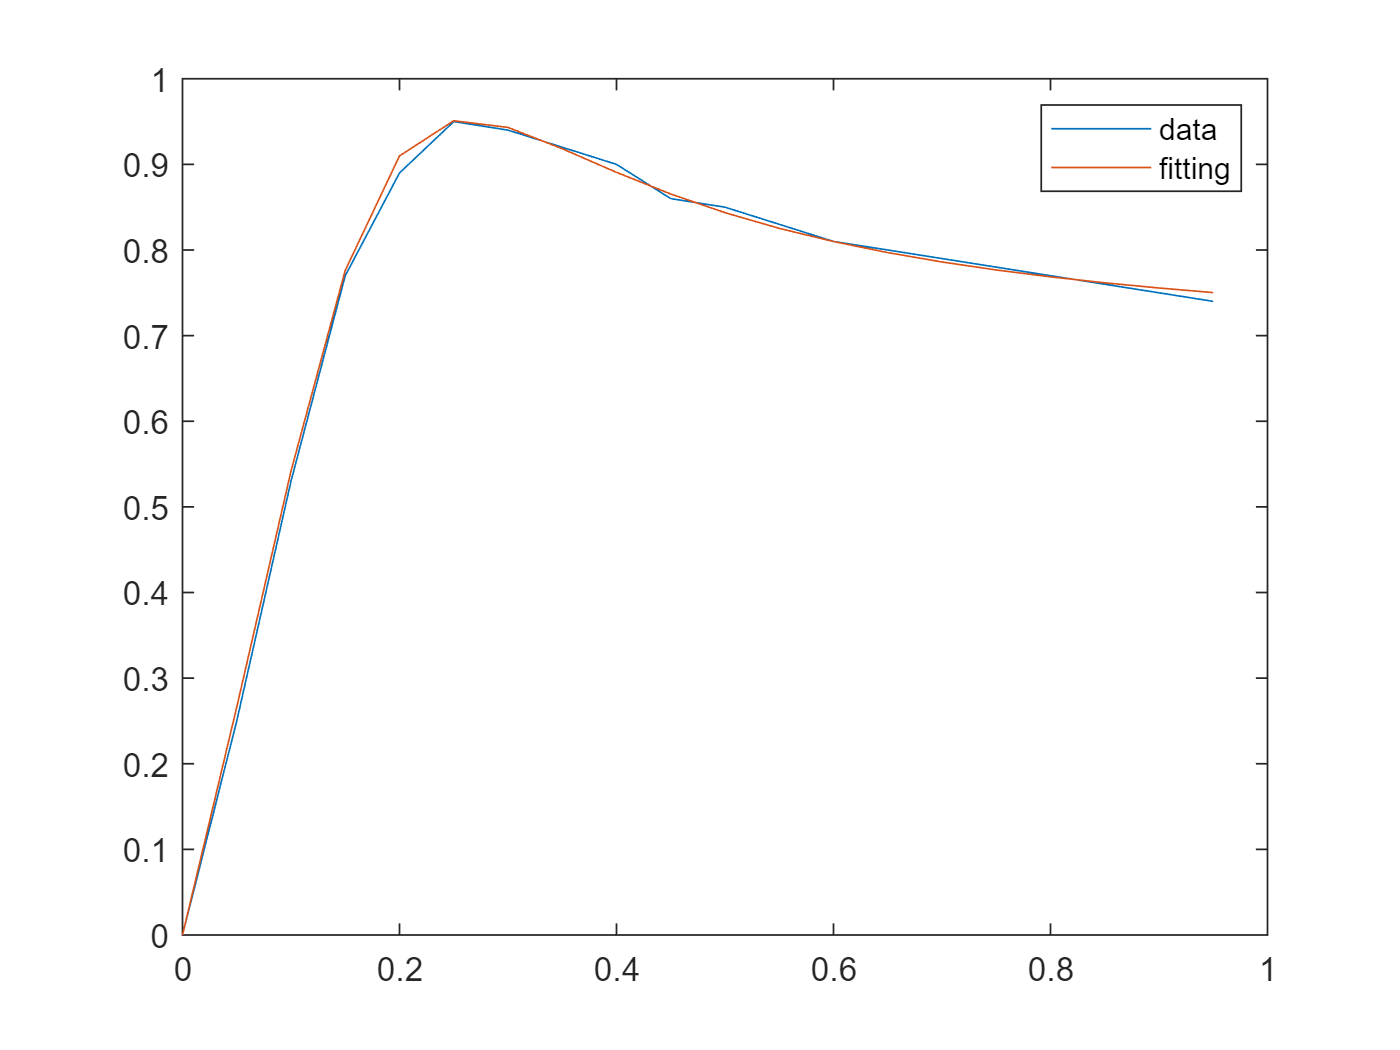

s_x = 0:0.05:0.95;
lf_normd = [0.0 0.25 0.53 0.77 0.89 0.95 0.94 0.92 0.90 0.86 0.85 0.83 0.81 0.80 0.79 0.78 0.77 0.76 0.75 0.74];
mu = magic_tireformula(s_x, 1.5, 0.952, -4.00);
figure 
plot(s_x, lf_normd)
hold on
plot(s_x, mu);
legend("data","fitting")

## Task2

syms F_fx F_rx F_fz F_rz omega_dot_f omega_dot_r v_dot_x 
syms m g L_f L_r F_air h theta J T_f mu_f mu_r RRC R

% Vertical
equ1 = 0 == F_fz + F_rz - m*g*cos(theta);
% Longitudinal
equ2 = 0 == F_fx + F_rx - F_air - m*v_dot_x - m*g*sin(theta);
% rotation round contact with ground
equ3 = 0 == -m*g*L_f + F_rz*(L_r+L_f) - (m*v_dot_x-F_air)*h;
equ4 = 0 == m*g*L_r - F_fz*(L_r+L_f) - (m*v_dot_x+F_air)*h;
% Equilibrium, rotational
equ5 = 0 == T_f - F_fz*RRC*R - F_fx*R - J*omega_dot_f;
equ6 = 0 == 0 - F_rz*RRC*R - F_rx*R - J*omega_dot_r;
% Constitutive equation
equ7 = F_fx == mu_f * F_fz;
equ8 = F_rx == mu_r * F_rz;

equ9 = 0 == F_rz*L_r - F_fz*L_f - (m*v_dot_x + F_air)*h;

equ = [equ1,equ2,equ5,equ6,equ7,equ8,equ9];
sol = solve(equ, [F_fx F_rx F_fz F_rz omega_dot_f omega_dot_r v_dot_x])

sol = struct with fields:
           F_fx: (mu_f*(L_r*g*m*cos(theta) + g*h*m*sin(theta) - g*h*m*mu_r*cos(theta)))/(L_f + L_r + h*mu_f - h*mu_r)
           F_rx: (mu_r*(L_f*g*m*cos(theta) - g*h*m*sin(theta) + g*h*m*mu_f*cos(theta)))/(L_f + L_r + h*mu_f - h*mu_r)
           F_fz: (L_r*g*m*cos(theta) + g*h*m*sin(theta) - g*h*m*mu_r*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r)
           F_rz: (L_f*g*m*cos(theta) - g*h*m*sin(theta) + g*h*m*mu_f*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r)
    omega_dot_f: (L_f*T_f + L_r*T_f + T_f*h*mu_f - T_f*h*mu_r - L_r*R*g*m*mu_f*cos(theta) - R*RRC*g*h*m*sin(theta) - R*g*h*m*mu_f*sin(theta) - L_r*R*RRC*g*m*cos(theta) + R*RRC*g*h*m*mu_r*cos(theta) + R*g*h*m*mu_f*mu_r*cos(theta))/(J*(L_f + L_r + h*mu…
    omega_dot_r: -((R*RRC + R*mu_r)*(L_f*g*m*cos(theta) - g*h*m*sin(theta) + g*h*m*mu_f*cos(theta)))/(J*(L_f + L_r + h*mu_f - h*mu_r))
        v_dot_x: -(F_air*L_f + F_air*L_r + F_air*h*mu_f - F_air*h*mu_r + L_f*g*m*sin(theta) + L_r*g*m*sin(theta) - L_f*g*m*mu_r*c

simplify(sol.F_fz)

$$ans = \frac{g\,m\,\left(L_{r}\,\cos\left(\theta \right)+h\,\sin\left(\theta \right)-h\,\mu_{r}\,\cos\left(\theta \right)\right)}{L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.F_rz)

$$ans = \frac{g\,m\,\left(L_{f}\,\cos\left(\theta \right)-h\,\sin\left(\theta \right)+h\,\mu_{f}\,\cos\left(\theta \right)\right)}{L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.omega_dot_f)

$$ans = \frac{L_{f}\,T_{f}+L_{r}\,T_{f}+T_{f}\,h\,\mu_{f}-T_{f}\,h\,\mu_{r}-L_{r}\,R\,g\,m\,\mu_{f}\,\cos\left(\theta \right)-R\,\mathrm{RRC}\,g\,h\,m\,\sin\left(\theta \right)-R\,g\,h\,m\,\mu_{f}\,\sin\left(\theta \right)-L_{r}\,R\,\mathrm{RRC}\,g\,m\,\cos\left(\theta \right)+R\,\mathrm{RRC}\,g\,h\,m\,\mu_{r}\,\cos\left(\theta \right)+R\,g\,h\,m\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)}{J\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.omega_dot_r)

$$ans = -\frac{R\,g\,m\,\left(\mathrm{RRC}+\mu_{r}\right)\,\left(L_{f}\,\cos\left(\theta \right)-h\,\sin\left(\theta \right)+h\,\mu_{f}\,\cos\left(\theta \right)\right)}{J\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.v_dot_x)

$$ans = -\frac{F_{\mathrm{air}}\,L_{f}+F_{\mathrm{air}}\,L_{r}+F_{\mathrm{air}}\,h\,\mu_{f}-F_{\mathrm{air}}\,h\,\mu_{r}+L_{f}\,g\,m\,\sin\left(\theta \right)+L_{r}\,g\,m\,\sin\left(\theta \right)-L_{f}\,g\,m\,\mu_{r}\,\cos\left(\theta \right)-L_{r}\,g\,m\,\mu_{f}\,\cos\left(\theta \right)}{m\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

function mu = magic_tireformula(slip,C,D,E0)
%----Common parameters-----------------------------------------------------
K  = 3*pi/180;
B  = atan(K)/(C*D);

%----Calculate the available friction--------------------------------------
mu = D*sin(C*atan(B*slip*100-E0*(B*slip*100-atan(B*slip*100))));

end